# **Matlab Challenge #3**

## **Andy Garcha**

**September 28, 2023**

**ENGE 1414 Section 90862**

% Set up the Import Options and import the data
opts = spreadsheetImportOptions("NumVariables", 2);

% Specify sheet and range
opts.Sheet = "Sheet1";
opts.DataRange = "A2:B25";

% Specify column names and types
opts.VariableNames = ["Minutes", "GameName"];
opts.VariableTypes = ["double", "categorical"];

% Specify variable properties
opts = setvaropts(opts, "GameName", "EmptyFieldRule", "auto");

% Import the data
data = readtable("C:\Users\Administrator\Documents\GitHub\ENGE-1414\ASSIGNMENTS\MATLAB Challenge #3 Data.xlsx", opts, "UseExcel", false);

% Clear temporary variables
clear opts

% Display results
data

data = 24×2 table
    Minutes     GameName  
    _______    ___________

       9       Outer Wilds
       0       N/A        
       0       N/A        
       0       N/A        
       0       N/A        
       0       N/A        
       0       N/A        
       0       N/A        
       0       N/A        
       0       N/A        
      30       Sifu       
      60       Sifu       
      12       Sifu       
       0       N/A        
      18       Outer Wilds
       0       N/A        


% create a dictionary to store games and their respective minutes 
% (side note: dr. wallwey told me to say this at the start of my program.
% i did not copy this off of the internet. i know what i'm doing and
% i love dictionaries.)
game_dict = dictionary("Test",0)


game_dict =

  dictionary (string ⟼ double) with 1 entry:

    "Test" ⟼ 0



clear keys
% Iterate through the table 24 times (as there are 24 hours in a day)
for k=1:24
    % create variables for both pieces of data we will use in each
    % iteration.
    minutes = table2array(data(k,"Minutes"))
    game_name = table2array(data(k,"GameName"))

    % check if a game was played during this hour
    if minutes ~= 0 & game_name ~= "N/A"
        % check if the game has been played before
        game_exists = false
        for l=1:length(keys(game_dict))
            game_keys = keys(game_dict)
            if game_keys(l) == game_name
                game_exists = true
            end
        end
        
        % if the game has been played before, add it to the total value
        if game_exists
            game_dict(game_name) = game_dict(game_name) + minutes
        % if the game has NOT been played before, make a new entry
        else
            game_dict(game_name) = minutes
        end
    end
end

minutes = 9

game_name = categorical
     Outer Wilds 


game_exists = logical
   0


game_keys = "Test"


game_dict =

  dictionary (string ⟼ double) with 2 entries:

    "Test"        ⟼ 0
    "Outer Wilds" ⟼ 9



minutes = 0

game_name = categorical
     N/A 


minutes = 0

game_name = categorical
     N/A 


minutes = 0

game_name = categorical
     N/A 


minutes = 0

game_name = categorical
     N/A 


minutes = 0

game_name = categorical
     N/A 


minutes = 0

game_name = categorical
     N/A 


minutes = 0

game_name = categorical
     N/A 


minutes = 0

game_name = categorical
     N/A 


minutes = 0

game_name = categorical
     N/A 


minutes = 30

game_name = categorical
     Sifu 


game_exists = logical
   0


game_keys = 2×1 string array
    "Test"
    "Outer Wilds"


game_keys = 2×1 string array
    "Test"
    "Outer Wilds"



game_dict =

  dictionary (string ⟼ double) with 3 entries:

    "Test"        ⟼ 0
    "Outer Wilds" ⟼ 9
    "Sifu"        ⟼ 30



minutes = 60

game_name = categorical
     Sifu 


game_exists = logical
   0


game_keys = 3×1 string array
    "Test"
    "Outer Wilds"
    "Sifu"


game_keys = 3×1 string array
    "Test"
    "Outer Wilds"
    "Sifu"


game_keys = 3×1 string array
    "Test"
    "Outer Wilds"
    "Sifu"


game_exists = logical
   1



game_dict =

  dictionary (string ⟼ double) with 3 entries:

    "Test"        ⟼ 0
    "Outer Wilds" ⟼ 9
    "Sifu"        ⟼ 90



minutes = 12

game_name = categorical
     Sifu 


game_exists = logical
   0


game_keys = 3×1 string array
    "Test"
    "Outer Wilds"
    "Sifu"


game_keys = 3×1 string array
    "Test"
    "Outer Wilds"
    "Sifu"


game_keys = 3×1 string array
    "Test"
    "Outer Wilds"
    "Sifu"


game_exists = logical
   1



game_dict =

  dictionary (string ⟼ double) with 3 entries:

    "Test"        ⟼ 0
    "Outer Wilds" ⟼ 9
    "Sifu"        ⟼ 102



minutes = 0

game_name = categorical
     N/A 


minutes = 18

game_name = categorical
     Outer Wilds 


game_exists = logical
   0


game_keys = 3×1 string array
    "Test"
    "Outer Wilds"
    "Sifu"


game_keys = 3×1 string array
    "Test"
    "Outer Wilds"
    "Sifu"


game_exists = logical
   1


game_keys = 3×1 string array
    "Test"
    "Outer Wilds"
    "Sifu"



game_dict =

  dictionary (string ⟼ double) with 3 entries:

    "Test"        ⟼ 0
    "Outer Wilds" ⟼ 27
    "Sifu"        ⟼ 102



minutes = 0

game_name = categorical
     N/A 


minutes = 0

game_name = categorical
     N/A 


minutes = 0

game_name = categorical
     N/A 


minutes = 14

game_name = categorical
     Outer Wilds 


game_exists = logical
   0


game_keys = 3×1 string array
    "Test"
    "Outer Wilds"
    "Sifu"


game_keys = 3×1 string array
    "Test"
    "Outer Wilds"
    "Sifu"


game_exists = logical
   1


game_keys = 3×1 string array
    "Test"
    "Outer Wilds"
    "Sifu"



game_dict =

  dictionary (string ⟼ double) with 3 entries:

    "Test"        ⟼ 0
    "Outer Wilds" ⟼ 41
    "Sifu"        ⟼ 102



minutes = 60

game_name = categorical
     Outer Wilds 


game_exists = logical
   0


game_keys = 3×1 string array
    "Test"
    "Outer Wilds"
    "Sifu"


game_keys = 3×1 string array
    "Test"
    "Outer Wilds"
    "Sifu"


game_exists = logical
   1


game_keys = 3×1 string array
    "Test"
    "Outer Wilds"
    "Sifu"



game_dict =

  dictionary (string ⟼ double) with 3 entries:

    "Test"        ⟼ 0
    "Outer Wilds" ⟼ 101
    "Sifu"        ⟼ 102



minutes = 60

game_name = categorical
     Outer Wilds 


game_exists = logical
   0


game_keys = 3×1 string array
    "Test"
    "Outer Wilds"
    "Sifu"


game_keys = 3×1 string array
    "Test"
    "Outer Wilds"
    "Sifu"


game_exists = logical
   1


game_keys = 3×1 string array
    "Test"
    "Outer Wilds"
    "Sifu"



game_dict =

  dictionary (string ⟼ double) with 3 entries:

    "Test"        ⟼ 0
    "Outer Wilds" ⟼ 161
    "Sifu"        ⟼ 102



minutes = 60

game_name = categorical
     Outer Wilds 


game_exists = logical
   0


game_keys = 3×1 string array
    "Test"
    "Outer Wilds"
    "Sifu"


game_keys = 3×1 string array
    "Test"
    "Outer Wilds"
    "Sifu"


game_exists = logical
   1


game_keys = 3×1 string array
    "Test"
    "Outer Wilds"
    "Sifu"



game_dict =

  dictionary (string ⟼ double) with 3 entries:

    "Test"        ⟼ 0
    "Outer Wilds" ⟼ 221
    "Sifu"        ⟼ 102



minutes = 45

game_name = categorical
     Outer Wilds 


game_exists = logical
   0


game_keys = 3×1 string array
    "Test"
    "Outer Wilds"
    "Sifu"


game_keys = 3×1 string array
    "Test"
    "Outer Wilds"
    "Sifu"


game_exists = logical
   1


game_keys = 3×1 string array
    "Test"
    "Outer Wilds"
    "Sifu"



game_dict =

  dictionary (string ⟼ double) with 3 entries:

    "Test"        ⟼ 0
    "Outer Wilds" ⟼ 266
    "Sifu"        ⟼ 102



minutes = 11

game_name = categorical
     Outer Wilds 


game_exists = logical
   0


game_keys = 3×1 string array
    "Test"
    "Outer Wilds"
    "Sifu"


game_keys = 3×1 string array
    "Test"
    "Outer Wilds"
    "Sifu"


game_exists = logical
   1


game_keys = 3×1 string array
    "Test"
    "Outer Wilds"
    "Sifu"



game_dict =

  dictionary (string ⟼ double) with 3 entries:

    "Test"        ⟼ 0
    "Outer Wilds" ⟼ 277
    "Sifu"        ⟼ 102




game_dict


game_dict =

  dictionary (string ⟼ double) with 3 entries:

    "Test"        ⟼ 0
    "Outer Wilds" ⟼ 277
    "Sifu"        ⟼ 102




clear my_string
% create a string to eventually output to the console.
my_string = "Here is your summary of your games from today:"

my_string = "Here is your summary of your games from today:"


% pie chart setup
values = []


values =

     []



labels = []


labels =

     []




% we now have the full game dictionary. now to make the output. 
% side note: we start at 2 because a key-value pair of "Test" --> 0 was inserted to
% set the data types of keys and values.
for m=2:length(keys(game_dict))
    % add to the string
    my_string = my_string + "\nYou played " + game_keys(m) + " for " + num2str(game_dict(game_keys(m))/60) + " hours."

    % add values to pie chart arrays
    values = [values game_dict(game_keys(m))]
    labels = [labels game_keys(m)]
end

my_string = "Here is your summary of your games from today:\nYou played Outer Wilds for 4.6167 hours."

values = 277

labels = "Outer Wilds"

my_string = "Here is your summary of your games from today:\nYou played Outer Wilds for 4.6167 hours.\nYou played Sifu for 1.7 hours."

values =    277   102


labels = 1×2 string array
    "Outer Wilds"    "Sifu"



% print out the string
fprintf(my_string)

Here is your summary of your games from today:
You played Outer Wilds for 4.6167 hours.
You played Sifu for 1.7 hours.

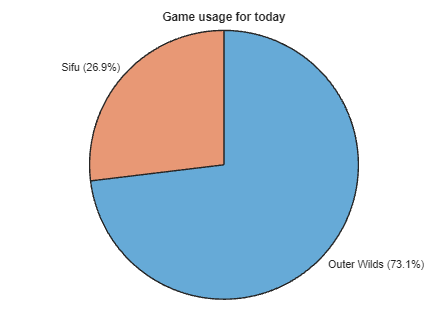


% create my pie chart
piechart(values, labels)
title("Game usage for today")


% calculate how many minutes the user has played today.
total_minutes = sum(values)

total_minutes = 379


% if the user has more than 300 minutes, output a warning.
if total_minutes > 300
    fprintf("Hey, you played more than five hours of video games today. Maybe reel it back in tomorrow!")
end

Hey, you played more than five hours of video games today. Maybe reel it back in tomorrow!